# **RS-HL-4: Data Transmission by MDP algorithm**

**The University of Texas at Austin**

**Hongseok Kim**

**6/13/2024**

## **Scope**

Create Data Transmission Dataset from given contact matrix

## I. Load the Data

clc; clear;
addpath('/workspace/RS_Dataset/')
load("RS_HL_3_Network_Graph_Generation.mat")

sat_to_sat_contact_3d_matrix(:,:,1);
gs_to_sat_contact_3d_matrix(:,:,1);

## II. Specify the start GS and end GS and get the contact schedule

start_gs = 3;

end_gs = 15;


start_gs_contact_schedule = zeros(48,5761);
end_gs_contact_schedule = zeros(48,5761);

for i = 1:48
start_gs_contact_schedule(i,:) = gs_to_sat_contact_3d_matrix(start_gs,i,:);
end_gs_contact_schedule(i,:) = gs_to_sat_contact_3d_matrix(end_gs,i,:);
end

start_gs_contact_schedule;
end_gs_contact_schedule;


## III. Contact Availability For GS

[row1,col1] = find(start_gs_contact_schedule == 1);


[row2,col2] = find(end_gs_contact_schedule == 1);

start_info = [row1,col1]

start_info =     16   179
    16   180
    16   181
    16   182
    16   183
    16   184
    16   185
    15   193
    15   194
    15   195


end_info = [row2,col2]

end_info =            6        1779
           6        1780
           6        1781
           6        1782
           6        1783
           6        1784
           5        1793
           5        1794
           5        1795
           5        1796


end_info = end_info(end_info(:,2) > start_info(1,2),:);

start_sat = start_info(1,1)

start_sat = 16


end_sat = end_info(1,1)

end_sat = 6


start_time = start_info(1,2)

start_time = 179


end_time = end_info(1,2)

end_time = 1779

## IV. MDP formulation

A = 1:48;
B = string(A');

MDP = createMDP(48,B);

time_stamp  = start_time;

gs_to_sat_matrix = gs_to_sat_contact_3d_matrix(:,:,time_stamp);
sat_to_sat_matrix = sat_to_sat_contact_3d_matrix(:,:,time_stamp);

MDP.TerminalStates = "s" + end_sat;

for i = 1:48
    for j = 1:48
        if sat_to_sat_matrix(i,j) == 1       
        MDP.T(i,j,j) = sat_to_sat_matrix(i,j);


        if i < 25
            if j < 25
                MDP.R(i,j,j) = -1;
            end
            if j > 24
                MDP.R(i,j,j) = -15;
            end
        end

        if i > 24
            if j > 24
                MDP.R(i,j,j) = -1;
            end
            if j < 25
                MDP.R(i,j,j) = -15;
            end
        end

        if j == end_sat
            if j < 25
                if i > 24
                 MDP.R(i,end_sat,end_sat) = 50;
                end
                else
                MDP.R(i,end_sat,end_sat) = 100;
            end

            if j > 24
                if i < 25
                MDP.R(i,end_sat,end_sat) = 50;
                end
                else
                MDP.R(i,end_sat,end_sat) = 100;
            end
        end

        end

        if sat_to_sat_matrix(i,j) == 0
        MDP.T(i,i,j) = 1;
        MDP.R(i,i,j) = -50;
        end
    end
end


## V. MDP Execution

env = rlMDPEnv(MDP);

env.ResetFcn = @() start_sat;

rng(0)

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
qTable = rlTable(obsInfo, actInfo);
qFunction = rlQValueFunction(qTable, obsInfo, actInfo);
qOptions = rlOptimizerOptions(LearnRate=1);

agentOpts = rlQAgentOptions;
agentOpts.DiscountFactor = 1;
agentOpts.EpsilonGreedyExploration.Epsilon = 0.9;
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 0.01;
agentOpts.CriticOptimizerOptions = qOptions;
qAgent = rlQAgent(qFunction,agentOpts); % #ok<NASGU> 

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 100;
trainOpts.MaxEpisodes = 500;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 13;
trainOpts.ScoreAveragingWindowLength = 30;

trainingStats = train(qAgent,env,trainOpts);

## VI. MDP Optimization Result

Data = sim(qAgent,env);

Satellites_list = reshape(Data.Observation.MDPObservations.Data, [],1)

Satellites_list =     16
    15
    14
    13
    12
    11
    34
     8
     7
     6



No_of_SATS_passed = size(Data.Observation.MDPObservations.Data)

No_of_SATS_passed =      1     1    10



Reward_list = Data.Reward.Data

Reward_list =     -1
    -1
    -1
    -1
    -1
   -15
   -15
    -1
   100



Total_reward = sum(Data.Reward.Data)

Total_reward = 64

## VII. Graph Plot

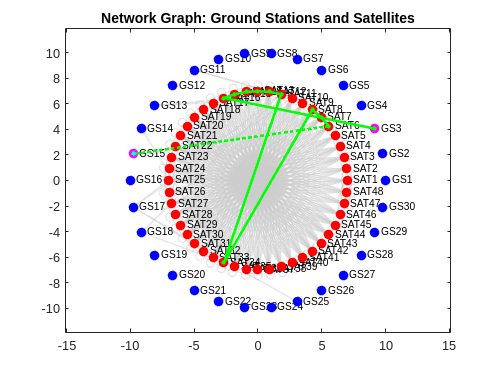

GS_to_Sat = gs_to_sat_contact_3d_matrix(:,:,time_stamp);
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,time_stamp);

% Make Datasat Handovering SAT / GS

Data_Transmisson_Sequence = zeros(length(Satellites_list)+1,2);

Data_Transmisson_Sequence(1,:) = [ground_station_x(start_gs), ground_station_y(start_gs)];


for ii = 1:length(Satellites_list)
Data_Transmisson_Sequence(ii+1,:) = [satellite_x(Satellites_list(ii)), satellite_y(Satellites_list(ii))];
end

Data_Transmission_End = [satellite_x(end_sat),satellite_y(end_sat);
                        ground_station_x(end_gs), ground_station_y(end_gs)];


% Plot the network graph
figure;
plot(G, 'XData', x, 'YData', y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1);
hold on;

% Plot the ground stations in blue and the satellites in red
plot(ground_station_x, ground_station_y, 'bo', 'MarkerSize', 7 , 'MarkerFaceColor', 'b');
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 7, 'MarkerFaceColor', 'r');




% plot(satellite_x(start_sat), satellite_y(stVII. Graph Plotart_sat), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'G');
% plot(satellite_x(end_sat), satellite_y(end_sat), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'G');
% plot(ground_station_x(start_gs), ground_station_y(start_gs), 'bo', 'MarkerSize', 10 , 'MarkerFaceColor', 'G');
plot(ground_station_x(start_gs), ground_station_y(start_gs), 'mo', 'MarkerSize', 7 , 'MarkerFaceColor', 'M');
plot(ground_station_x(end_gs), ground_station_y(end_gs), 'mo', 'MarkerSize', 7 , 'MarkerFaceColor', 'M');
plot(Data_Transmisson_Sequence(:,1),Data_Transmisson_Sequence(:,2),'go', 'MarkerSize', 3, 'MarkerFaceColor', 'G')
plot(Data_Transmisson_Sequence(:,1),Data_Transmisson_Sequence(:,2),'g','LineWidth',2);
plot(Data_Transmission_End(:,1),Data_Transmission_End(:,2),'LineStyle',':','Color','g','LineWidth',2);
plot(ground_station_x(end_gs), ground_station_y(end_gs), 'co', 'MarkerSize', 3 , 'MarkerFaceColor', 'c');

% Adjust the axis limits to fit the plot
axis equal;
title('Network Graph: Ground Stations and Satellites');